clear all,close all,clc
k=  3

k = 3

Cs=zpk([],[1],k)


Cs =
 
    3
  -----
  (s-1)
 
Continuous-time zero/pole/gain model.



Cg=zpk([],[-2],1)


Cg =
 
    1
  -----
  (s+2)
 
Continuous-time zero/pole/gain model.



CsCg=series(Cs,Cg)


CsCg =
 
       3
  -----------
  (s+2) (s-1)
 
Continuous-time zero/pole/gain model.




sys=feedback(CsCg,1,-1)


sys =
 
        3
  -------------
  (s^2 + s + 1)
 
Continuous-time zero/pole/gain model.



pole=pole(sys)

pole =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i



t = 0:0.01:4

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


input = exp(t)

input =     1.0000    1.0101    1.0202    1.0305    1.0408    1.0513    1.0618    1.0725    1.0833    1.0942    1.1052    1.1163    1.1275    1.1388    1.1503    1.1618    1.1735    1.1853    1.1972    1.2092    1.2214    1.2337    1.2461    1.2586    1.2712    1.2840    1.2969    1.3100    1.3231    1.3364    1.3499    1.3634    1.3771    1.3910    1.4049    1.4191    1.4333    1.4477    1.4623    1.4770    1.4918    1.5068    1.5220    1.5373    1.5527    1.5683    1.5841    1.6000    1.6161    1.6323


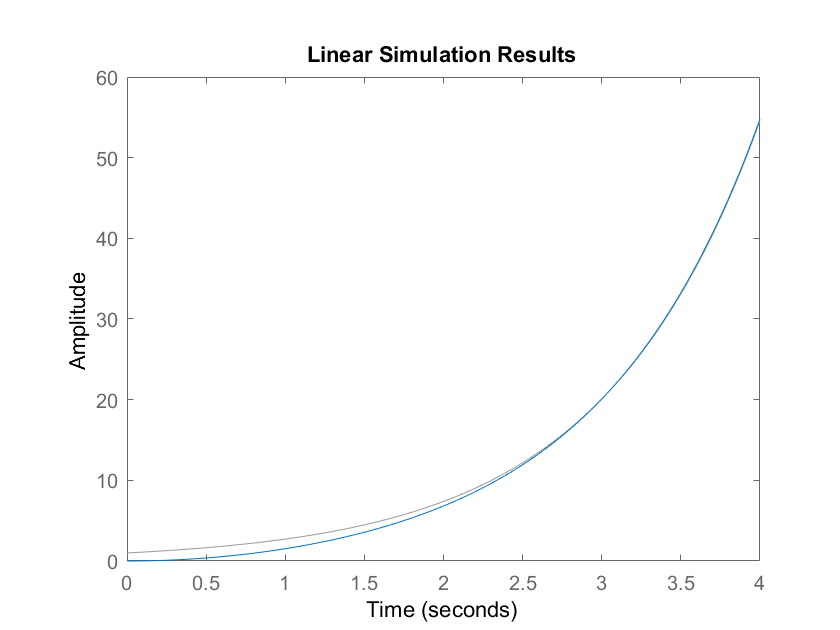

figure(2)
lsim(sys,input,t)